% Jeremiah Sullivan
% EC508, Wireless Communicaton
% Mini Project 3, April 2019
clc; close all; clear all; 
%% Slow Fading Channels
% Consider a SIMO channel with L receive antennas,
%       y[m] = h x[m]+w[m] 
%           where w[m] is i.i.d. CN (0, N_{0}I), 
%           x[m] satisfies power constraint P, 
%           h ~ CN (0, I) and is known only to the receiver.

% Part A) 
% To get started, write code to compute the closed-form outage capacity 
% that we derived in class for the L = 1 case. 
% Additionally, write code to find the outage capacity empirically. 
%   For SNR = 0dB to 20dB (with 1dB spacing)
%   plot the capacity curves from these two methods for pout = 0.01, 0.05, 0.1.
%   (If you’ve done everything right, they should coincide.)
pOut     = [0.01, 0.05, 0.1];  SNRdb = 0:20; 
SNR       = 10.^(SNRdb/10);

R           =   [ ];  % rate; 
L           =     1;    % Diversity
M          = 1E5; % 1E7 ~~ max
h = 1/sqrt(2) * randn(L,M) + 1j/sqrt(2) * randn(L,M); 
fprintf('The channel gains have a mean of %01.4f and a standard deviation of %1.4f', abs(mean(h)), std(h))

The channel gains have a mean of 0.0046 and a standard deviation of 1.0010

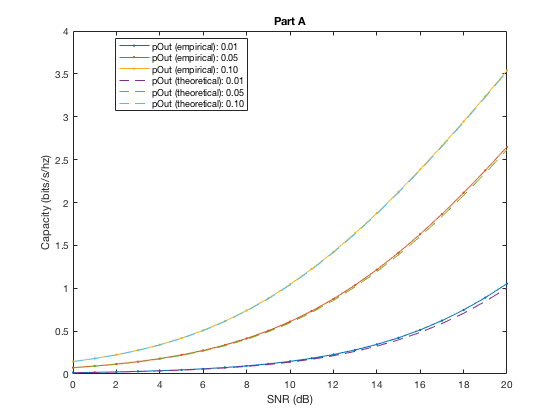

w = 1/sqrt(2) * randn(L,M) + 1j/sqrt(2) * randn(L,M);

% x = sqrt(SNR)*(2*randi([0 1] - 1));
% y = h * x + w;
C = zeros(length(pOut), length(SNRdb)); 
for i = 1:length(pOut)
         E           = log2(1 + sort(abs(h').^2) .*SNR);  % Each SNR should form a column (ie, MxSNR); 
         Es         = E;  % sort(E, 'ascend');                      % sort them in ascending order
         C(i,:)      = Es(M*pOut(i),:);                                % take the value of the sorted trial in position pout×M.
end
figure; 
plot(SNRdb, (C), '.-'); xlabel('SNR (dB)'); ylabel('Capacity (bits/s/hz)'); 
exactC = log2(1 + log( 1 ./ (1 - pOut')).*SNR); 
hold on; plot(SNRdb, exactC, '--'); title('Part A'); 
legend([sprintfc('pOut (empirical): %01.2f', pOut'); (sprintfc('pOut (theoretical): %01.2f', pOut'))], 'location', 'best')

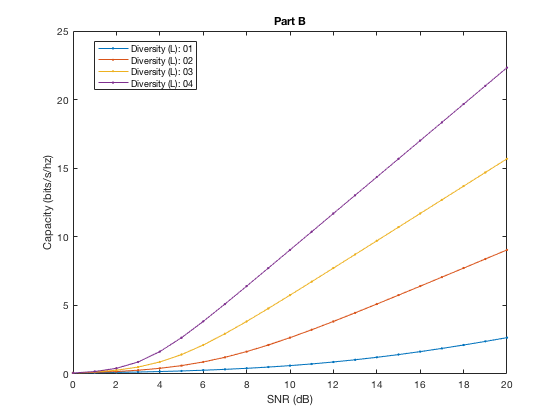


%% Generalize to any L
pOut = 0.05; 
figure; clear C E Es;
L = 1:4;
for j = 1:length(L)
    for i = 1:length(pOut)
        E           = log2(1 + sort(abs(h').^2) .*SNR.^L(j));  % Each SNR should form a column (ie, MxSNR);
        Es         = E;  % sort(E, 'ascend');                       % sort them in ascending order
        C(j,:)     = Es(M*pOut(i),:);                                 % take the value of the sorted trial in position pout×M.
    end
end
plot(SNRdb, (C), '.-'); hold on; 
xlabel('SNR (dB)'); ylabel('Capacity (bits/s/hz)'); title('Part B'); 
legend(sprintfc('Diversity (L): %02.0f', L), 'location', 'best'); 

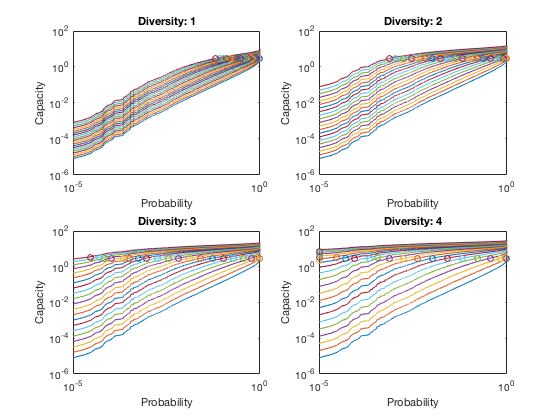


%% Outage Capacity vs. Fixed Capacity
% Confused by ||h||^2 = L
SNRdb = -10:20; SNR = 10.^(SNRdb./10); 
for pOut = [0.01, 0.1]
    for L = 1:4
    end
end

%% Fix target rate
figure; clc;
SNRdb = 0:20; SNR = 10.^(SNRdb./10); 
R = 3; pOut = zeros(length(L), length(SNR)); 
for L = 1:4
    E        = log2(1 + sort(abs(h').^2) .*SNR.^L);     % Each SNR should form a column (ie, MxSNR); 
    Es      = E;  % sort(E, 'ascend');                      % sort them in ascending order
    if ~all((R > min(E)) & R< max(E)); warning([ 'Requested value not in range. L = ' num2str(L)]); end
    [~, I]  = min(abs(Es - R));   % Find the closest value
    pOut(L, :) = I/M;                       % Transform that value into a probability
    if 1 % DEBUG
        subplot(2,2,L); 
        loglog(linspace(0,1, length(h)),  E); hold on;
        xlabel('Probability');  ylabel('Capacity'); 
        for i = 1:length(SNR)
            plot(I(i)./length(h), E(I(i), i), 'o');
        end
        title(['Diversity: ', num2str(L)]); 
    end
end

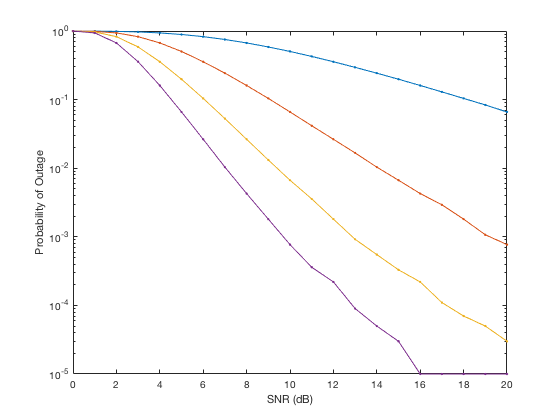

figure; semilogy(SNRdb, pOut, '.-'); 
xlabel('SNR (dB)'); ylabel('Probability of Outage')

# PROBLEM 2